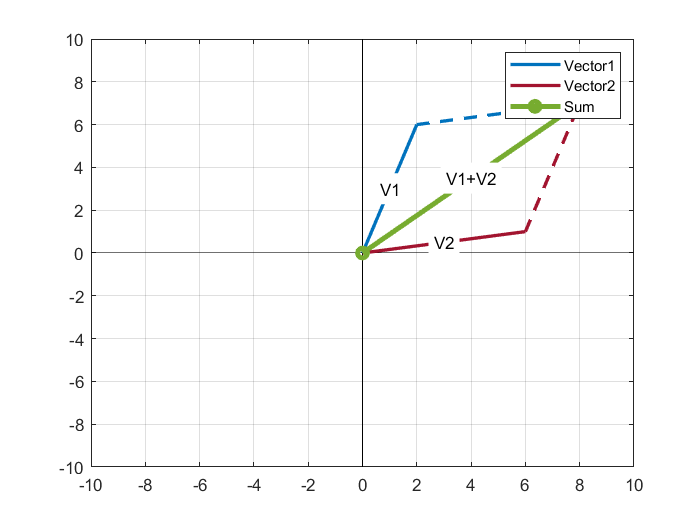

clc
clear all

V1x =2; V1y =  6;
V2x =6; V2y =1;


x1 = [0 V1x];
y1 = [0 V1y];

x2 = [0 V2x];
y2 = [0 V2y];

sumx = x1 + x2;
sumy = y1 + y2;


ghostx1 = [x1(2) sumx(2)];
ghosty1 = [y1(2) sumy(2)];

ghostx2 = [x2(2) sumx(2)];
ghosty2 = [y2(2) sumy(2)];


plot([-10 10],[0 0],"Color",'black')
hold on 
plot([0 0],[-10 10],"Color",'black')

plot(x1, y1, "Color",'#0072BD',LineWidth=2)
plot(x2, y2,'Color','#A2142F',LineWidth=2)
plot(sumx,sumy,'-o','Color','#77AC30',LineWidth=3);

plot(ghostx1,ghosty1, '--', 'Color','#0072BD',LineWidth=2);
plot(ghostx2,ghosty2, '--','Color','#A2142F',LineWidth=2);

text(x1(2)/2,y1(2)/2,['V1'],HorizontalAlignment='center', BackgroundColor='w')
text(x2(2)/2,y2(2)/2,['V2'],HorizontalAlignment='center',BackgroundColor='w')
text(sumx(2)/2,sumy(2)/2,['V1+V2'],HorizontalAlignment='center',BackgroundColor='w')

% xlim([-10 10]);
% ylim([-10 10]);
legend('','','Vector1','Vector2','Sum')
grid on
hold off